syms theta_1 theta_2 theta_3 theta_4;

a1 = 0.06;
a2 = 0.14;
a3 = 0.16;
a4 = 0.2;

eqn1 = (a1*cos(theta_1)) + (a2*cos(theta_1+theta_2)) + (a3*cos(theta_1+theta_2+theta_3)) - a4;
eqn2 = (a1*sin(theta_1)) + (a2*sin(theta_1+theta_2)) + (a3*sin(theta_1+theta_2+theta_3));
eqn3 = theta_1 + theta_2 + theta_3 + theta_4 - (4*pi);

solution = solve([eqn1,eqn2,eqn3],[theta_2,theta_3,theta_4]);

theta_2_1 = solution.theta_2(1);
theta_3_1 = solution.theta_3(1);
theta_4_1 = solution.theta_4(1);


% Using chain rule : theta_2_dot = (d(theta_2)/d(theta_1))*theta_1_dot
theta_d_2 = diff(solution.theta_2(1),theta_1);
theta_d_3 = diff(solution.theta_3(1),theta_1);
theta_d_4 = diff(solution.theta_4(1),theta_1);

% Using chain rule for ang accl at constant theta_1 rpm
theta_dd_2 = diff(theta_d_2,theta_1);
theta_dd_3 = diff(theta_d_3,theta_1);
theta_dd_4 = diff(theta_d_4,theta_1);

t = 0:0.1:10;


th2 = zeros(size(t));
th3 = zeros(size(t));
th4 = zeros(size(t));

th2_d = zeros(size(t));
th3_d = zeros(size(t));
th4_d = zeros(size(t));

th2_dd = zeros(size(t));
th3_dd = zeros(size(t));
th4_dd = zeros(size(t));

%Initial and boundary conditions
th1_i = pi/4; th1_d_i = 1; th1_dd = 0;

th1 = th1_i + (th1_d_i*t);
j = 1;
for i = t

    th2(j) = vpa(subs(theta_2_1,theta_1,th1(j)));
    th3(j) = vpa(subs(theta_3_1,theta_1,th1(j)));
    th4(j) = vpa(subs(theta_4_1,theta_1,th1(j)));
    
    th2_d(j) = (th1_d_i)*vpa(subs(theta_d_2,theta_1,th1(j)));
    th3_d(j) = (th1_d_i)*vpa(subs(theta_d_3,theta_1,th1(j)));
    th4_d(j) = (th1_d_i)*vpa(subs(theta_d_4,theta_1,th1(j)));

    th2_dd(j) = (th1_d_i)*(th1_d_i)*vpa(subs(theta_dd_2,theta_1,th1(j)));
    th3_dd(j) = (th1_d_i)*(th1_d_i)*vpa(subs(theta_dd_3,theta_1,th1(j)));
    th4_dd(j) = (th1_d_i)*(th1_d_i)*vpa(subs(theta_dd_4,theta_1,th1(j)));
    
    j = j+1;
end


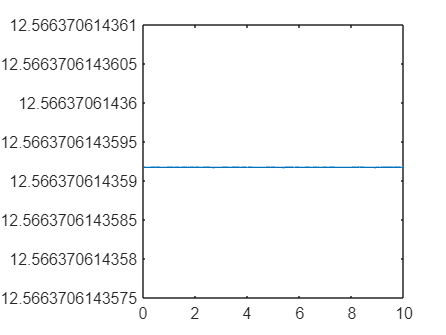

plot(t,th1+th2+th3+th4)

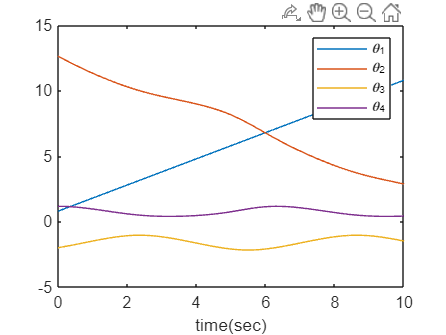

plot(t,th1,t,th2,t,th3,t,th4)

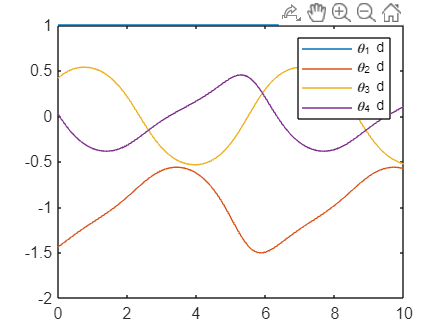

plot(t,th1_d_i*ones(size(t)),t,th2_d,t,th3_d,t,th4_d);

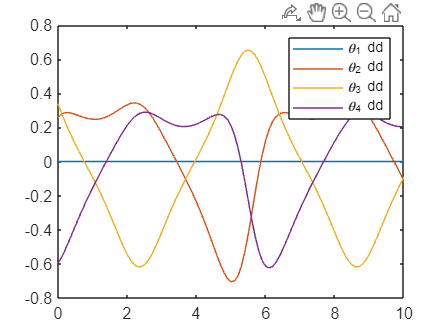

plot(t,th1_dd*ones(size(t)),t,th2_dd,t,th3_dd,t,th4_dd);